# Intro to Computational Imaging (ci) Classes

ciCamera is one of a set of classes that allow experimentation with computational imaging more directly than the previous "lower-level" scene, oi, sensor, and ip structs. Along with ciScene, ciCModule, and ciIP, it provides a programmable wrapper that allows users to create "cameras" that have a variety of algorithms for deciding how to capture a scene, and then how to process one or more captures, potentially even from more than one camera module (ciCModule).

History: Initial Version: D. Cardinal 12/2020

ieInit();

setpref('ISET', 'benchmarkstart', cputime); % if I just put it in a variable it gets cleared:(
setpref('ISET', 'tStart', tic);

% ciBurstCamera is a sub-class that implements simple HDR and Burst
% capture and processing
ourCamera = ciBurstCamera(); 
% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('NikonD100Sensor');
ourCamera.cmodule = ciCModule('sensor', sensor); % default

Now we define our scene. The Cornell Box + Bunny is part of iset3d, and is set up to help us by labeling the assets in such a way that we can add motion to them:

scenePath = 'Cornell_BoxBunnyChart';        
sceneName = 'cornell box bunny chart';
sceneLuminance = 200;
numRays = 32;
ourScene = ciScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance) % , 'lensFile','dgauss.22deg.12.5mm.json');

Read 11 materials
Read 3 textures
Reading C4D geometry information.


ourScene =   ciScene with properties:

             sceneType: "pbrt"
          initialScene: ''
        sceneFileNames: []
        imageFileNames: []
                 thisR: [1×1 recipe]
             scenePath: 'Cornell_BoxBunnyChart'
             sceneName: 'cornell box bunny chart'
            resolution: [512 512]
               numRays: 32
             numFrames: 1
              expTimes: 0.5000
    allowsCameraMotion: 1
          cameraMotion: []
    allowsObjectMotion: 1
          objectMotion: []
              lensFile: ''
        sceneLuminance: 200


% lensFile doesn't work right yet, as we haven't added oi processing

This sets the Stanford bunny in motion with a vertical movement and a tiny rotation. Later we'll show how the camera can also be set in motion.

% Move the bunny up, with slow rotation
ourScene.objectMotion = {{'Default_B', [0, 15, 0], [1, 1, 1]}};

For the simplest case we ask our camera to take a picture. By deault it uses the 'Auto' intent. Using 'Burst' will capture more frames if the camera type we are using supports it. 'HDR' will also fire a burst, but bracketed.

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overw

ans = "Scene luminance is: 200.000000"

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overw

ans = "Scene luminance is: 200.000000"

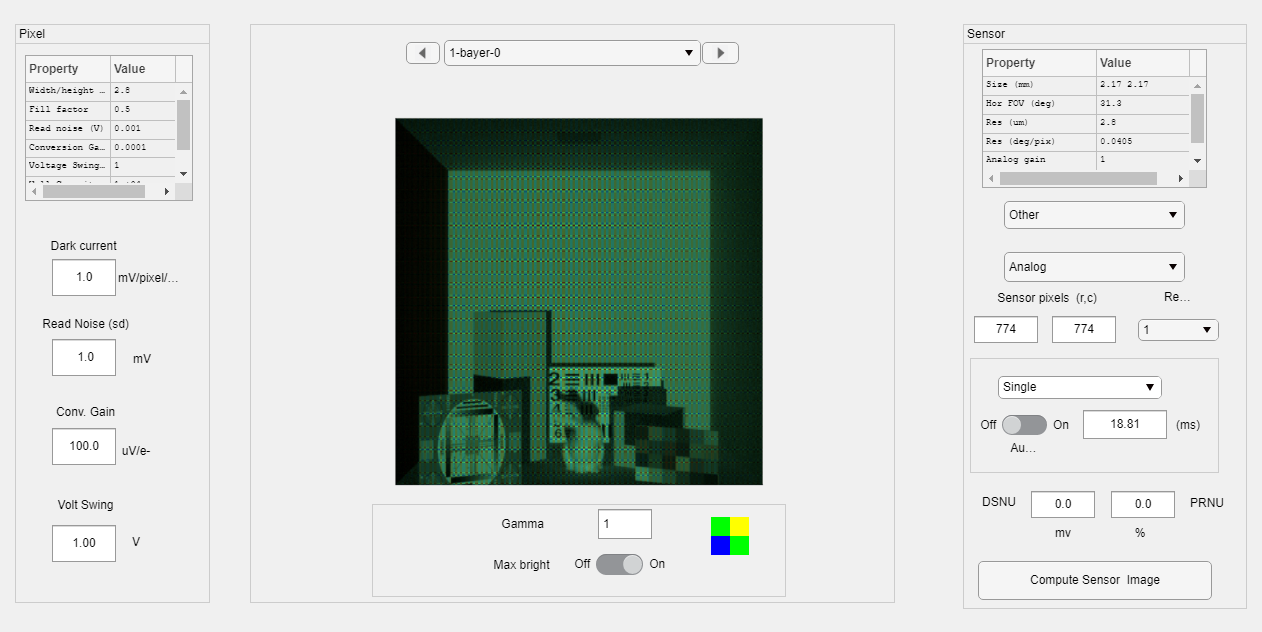

autoImage = ourCamera.TakePicture(ourScene, 'Auto',...
    'imageName','Auto Mode');

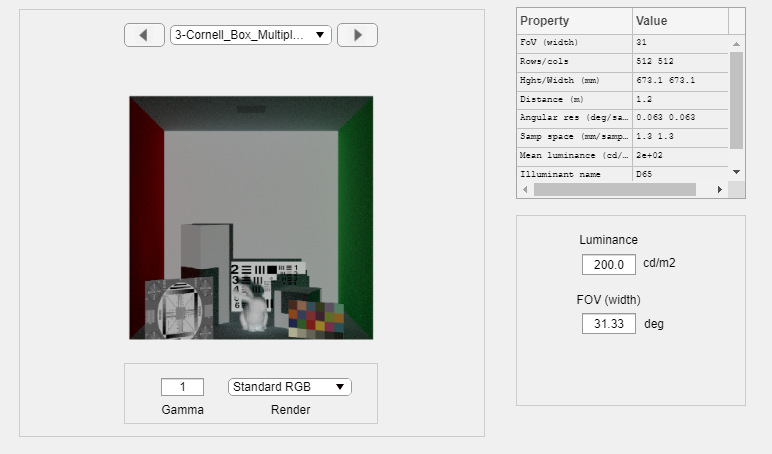

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overw

ans = "Scene luminance is: 200.000000"

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overw

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file 

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file 

ans = "Scene luminance is: 200.000000"

ieAddObject(autoImage); 

hdrImage = ourCamera.TakePicture(ourScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR Example');

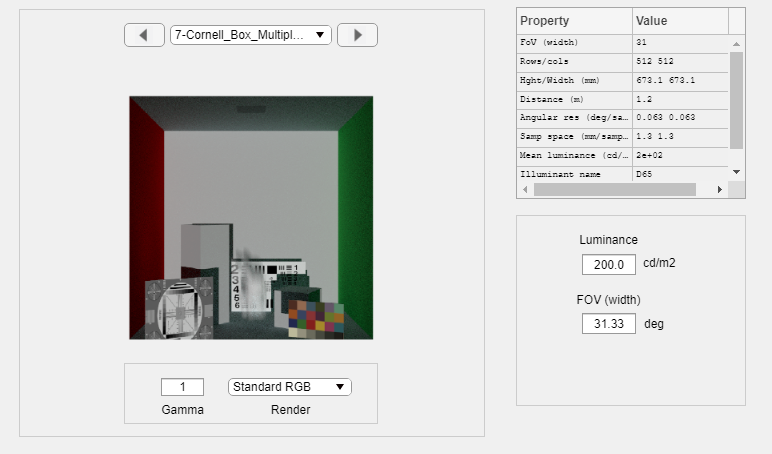

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overw

ans = "Scene luminance is: 200.000000"

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overw

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file 

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file 

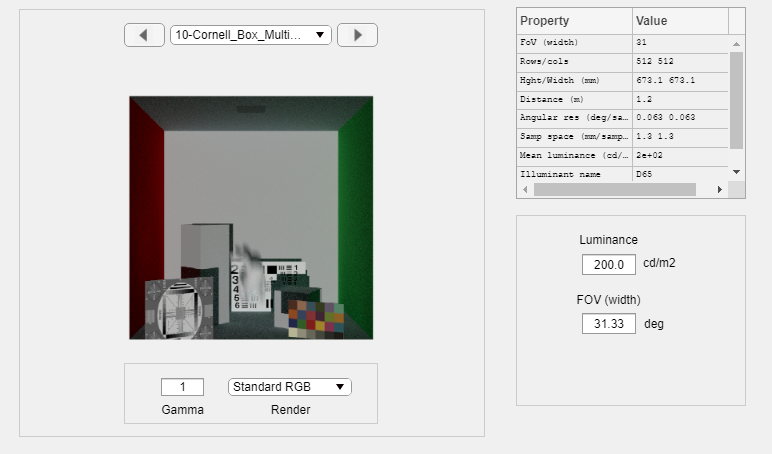

ans = "Scene luminance is: 200.000000"

ieAddObject(hdrImage); 

burstImage = ourCamera.TakePicture(ourScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst Example');

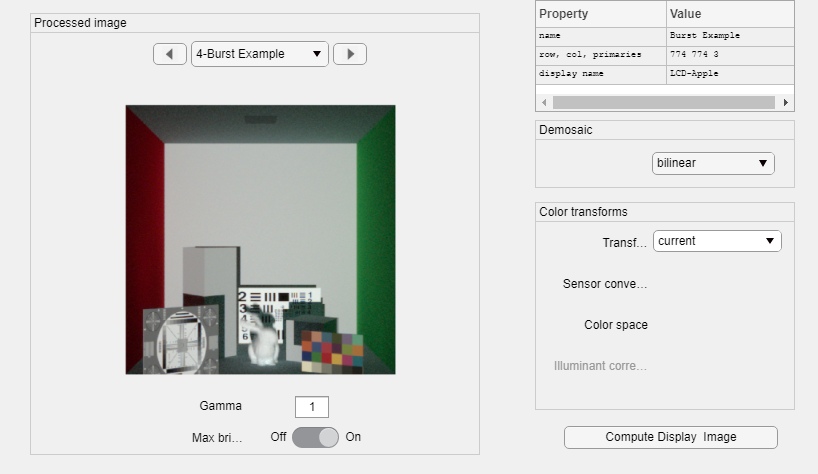

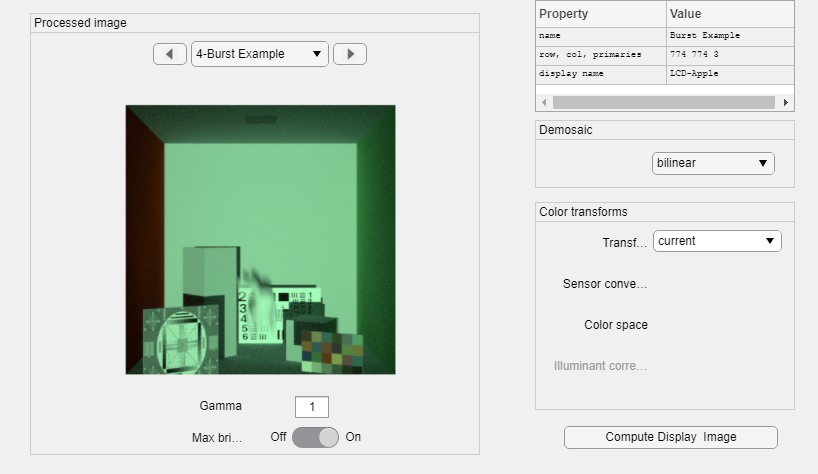

ieAddObject(burstImage); 

ipWindow(); % show the results

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overw

ans = "Scene luminance is: 200.000000"

New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overw

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file 

Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file 

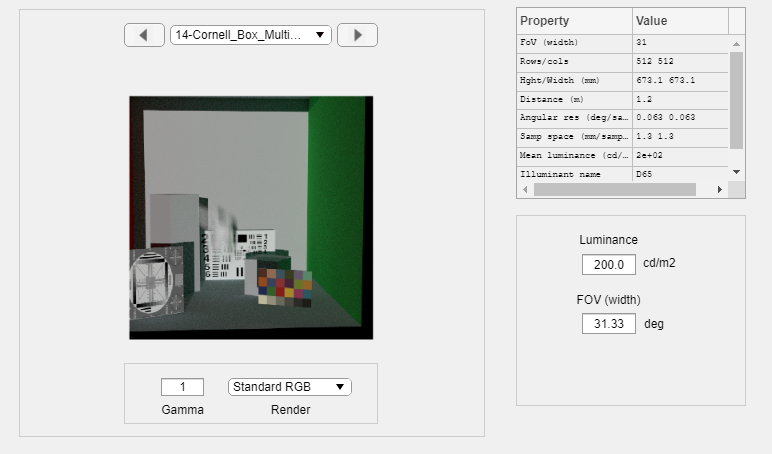

ans = "Scene luminance is: 200.000000"

% Add some camera motion
% Note that we don't have a way to move the camera during frames (yet)
ourScene.cameraMotion = {{'unused', [0, 0, 0], [2, 2, 2]}};
% now see what the burst looks like with the camera rotating
finalImage = ourCamera.TakePicture(ourScene, 'Burst', 'numBurstFrames', 3, 'imageName','Burst with Camera Motion');

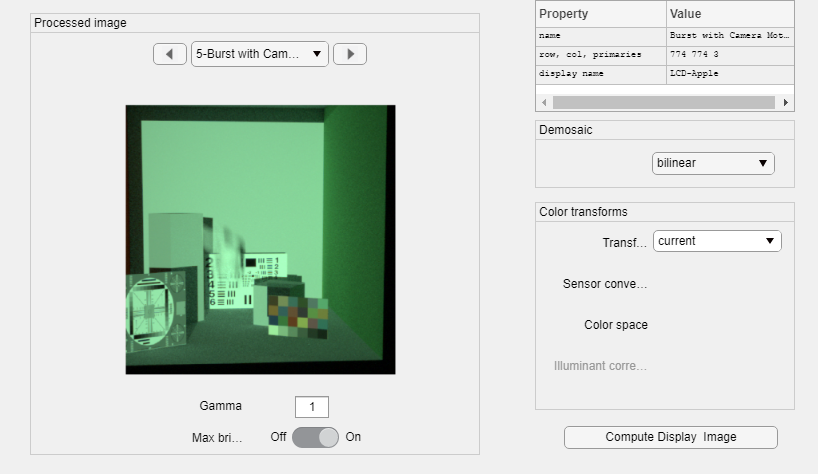

ieAddObject(finalImage);
ipWindow(); % show the result of a burst of images


tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("ciCam ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

ciCam ran  on: NVIDIA Corporation Quadro T2000/PCIe/SSE2with driver version: 4.6.0 NVIDIA 452.41


disp(strcat("ciCam ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

ciCam ran  in: 239 seconds of CPU time.


disp(strcat("ciCam ran  in: ", string(tTotal), " total seconds."));

ciCam ran  in: 950.8878 total seconds.
